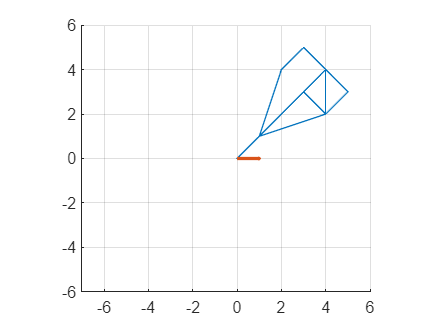

clf
clear
load('MT1A-G9-avbildningar.mat')
origo = [0; 0];
%drawArrow(origo, A)
hold on
grid on
axis equal
xlim([-7.0 6.0])
ylim([-6.0 6.0])

%X = [3, 2, 4, 4, 2, 4, 5, 2; 2, 3, 1, 5, 1, 3, 5, 3];

X = [0, 1, 2, 3, 4, 5, 4, 3, 4, 4, 1, 3;
     0, 1, 4, 5, 4, 3, 2, 3, 4, 2, 1, 3];
xLine = [1;
         0];

%X = randi(10, 2, 15)

plot(X(1,:), X(2, :))
drawArrow(origo, xLine)

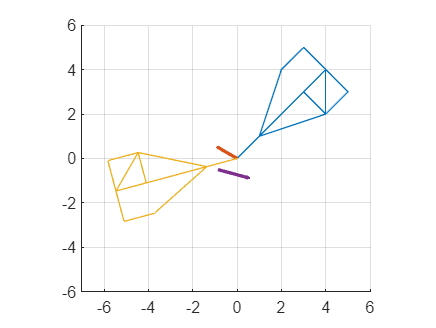

clf
hold on
grid on
axis equal
xlim([-7.0 6.0])
ylim([-6.0 6.0])

Bx = B*X;
BxLine = B*xLine;
plot(X(1,:), X(2, :))
drawArrow(origo, BxLine)
plot(Bx(1,:), Bx(2, :))
drawArrow(B(1,:), B(2,:))

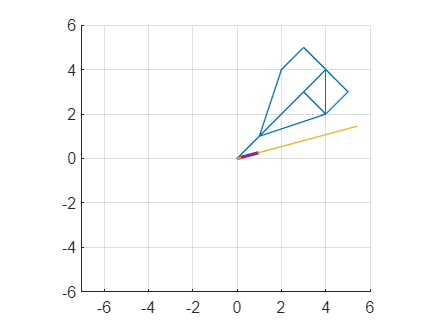

clf
hold on
grid on
axis equal
xlim([-7.0 6.0])
ylim([-6.0 6.0])

Cx = C*X;
CxLine = C*xLine;
plot(X(1,:), X(2, :))
drawArrow(origo, CxLine)
plot(Cx(1,:), Cx(2, :))
drawArrow(C(1,:), C(2,:))

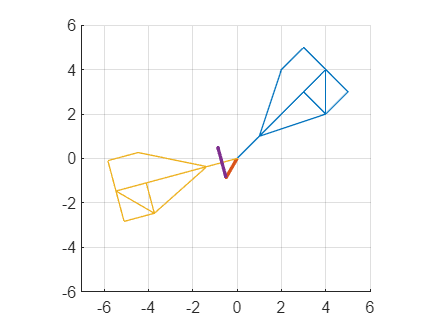

clf
hold on
grid on
axis equal
xlim([-7.0 6.0])
ylim([-6.0 6.0])

Ax = A*X;
AxLine = A*xLine;
plot(X(1,:), X(2, :))
drawArrow(origo, AxLine)
plot(Ax(1,:), Ax(2, :))
drawArrow(A(1,:), A(2,:))

clf
hold on
grid on
axis equal
xlim([-7.0 6.0])
ylim([-6.0 6.0])
% A like -pi/2
Bx = B*X

Bx =          0   -1.3660   -3.7321   -5.0981   -5.4641   -5.8301   -4.4641   -4.0981   -5.4641   -4.4641   -1.3660   -4.0981
         0   -0.3660   -2.4641   -2.8301   -1.4641   -0.0981    0.2679   -1.0981   -1.4641    0.2679   -0.3660   -1.0981


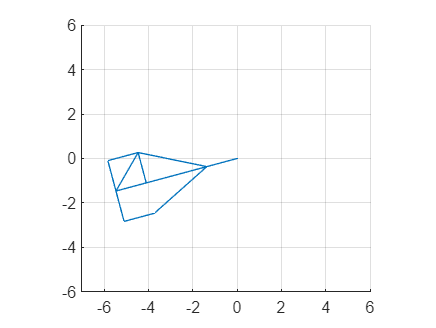

plot(Bx(1,:), Bx(2, :))

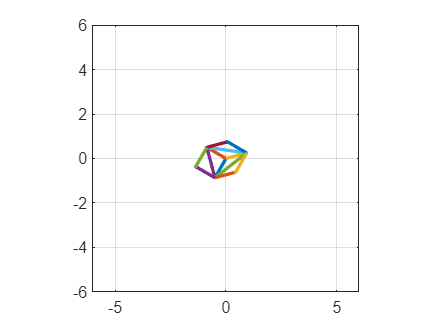

clf
drawArrow(origo, A) % blue
hold on
grid on
axis equal
axis([-6 6 -6 6])
drawArrow(origo, B)
drawArrow(origo, C)
drawArrow(A, B)
drawArrow(A, C)
drawArrow(B, C)
drawArrow(B, B + C)
drawArrow(C, B + C)
drawArrow(A, A + C)
drawArrow(C, A + C)
drawArrow(A, A + B)
drawArrow(B, A + B)

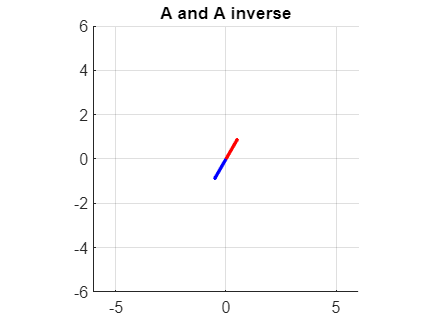

% 2
clf
hold on
grid on
axis equal
axis([-6 6 -6 6])
drawArrow(origo, A, 'blue')
drawArrow(origo, -A, 'red')
title('A and A inverse')

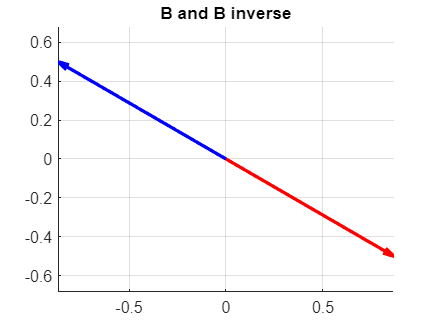

clf
hold on
grid on
axis equal
drawArrow(origo, B, 'blue')
drawArrow(origo, -B, 'red')
title('B and B inverse')

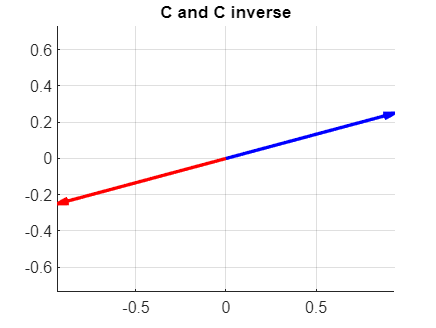

clf
hold on
grid on
axis equal
drawArrow(origo, C, 'blue')
drawArrow(origo, -C, 'red')
title('C and C inverse')

%drawArrow(origo, invC)
%drawArrow(origo, invA)

% like 3
clf
hold on
grid on
axis equal
A1 = A(:,1)

A1 =    -0.5000
   -0.8660


A2 = A(:,2)

A2 =    -0.8660
    0.5000


%det(A)
eig(A)

ans =     -1
     1


[valuesA, vectorsA] = eig(A)

valuesA =    -0.8660   -0.5000
   -0.5000    0.8660


vectorsA =     -1     0
     0     1


A

A =    -0.5000   -0.8660
   -0.8660    0.5000


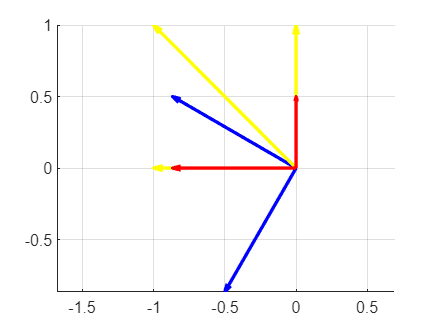

drawArrow(origo, A(:,1), 'blue')
drawArrow(origo, A(:,2), 'blue')
drawArrow(origo, vectorsA(:,1), 'yellow')
drawArrow(origo, vectorsA(:,2), 'yellow')
drawArrow(origo, eig(A), 'yellow')
%drawArrow(origo, A(:,1) + A(:,2), 'yellow')
%drawArrow(origo, vectorsA(:,1) * valuesA(1), 'red')
%drawArrow(origo, vectorsA(:,2) * valuesA(2), 'red')
drawArrow(origo, vectorsA(:,1) * valuesA(1) * -1, 'red')
drawArrow(origo, vectorsA(:,2) * valuesA(2) * -1, 'red')

%drawArrow(origo, A1, 'yellow')
%drawArrow(origo, A2, 'yellow')
%drawArrow(origo, valuesA, 'yellow')
%drawArrow(origo, vectorsA, 'yellow')
%drawArrow(origo, vectorsA, 'yellow')

% like 4
clf
hold on
grid on
axis equal
drawArrow(origo, C(:,1), 'blue')
drawArrow(origo, C(:,2), 'blue')
[vectorsC, valuesC] = eig(C)

vectorsC =     0.2588   -0.9659
   -0.9659   -0.2588


valuesC =     0.0000         0
         0    1.0000


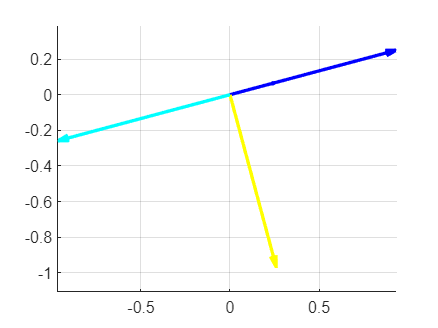

drawArrow(origo, vectorsC(:,1), 'yellow')
drawArrow(origo, vectorsC(:,1) * valuesC(1,1), 'black')
drawArrow(origo, vectorsC(:,2), 'red')
drawArrow(origo, vectorsC(:,2) * valuesC(2,2), 'cyan')

% like 5
clf
hold on
grid on
axis equal
A

A =    -0.5000   -0.8660
   -0.8660    0.5000


B

B =    -0.8660   -0.5000
    0.5000   -0.8660


newMatrix1 = B*A

newMatrix1 =     0.8660    0.5000
    0.5000   -0.8660


newMatrix2 = A*B

newMatrix2 =     0.0000    1.0000
    1.0000   -0.0000


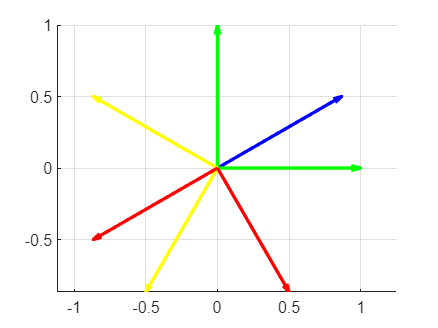

drawArrow(origo, newMatrix1(1,:), 'blue')
drawArrow(origo, newMatrix1(2,:), 'blue')
drawArrow(origo, newMatrix2(1,:), 'green')
drawArrow(origo, newMatrix2(2,:), 'green')
drawArrow(origo, A(1,:), 'yellow')
drawArrow(origo, A(2,:), 'yellow')
drawArrow(origo, B(1,:), 'red')
drawArrow(origo, B(2,:), 'red')